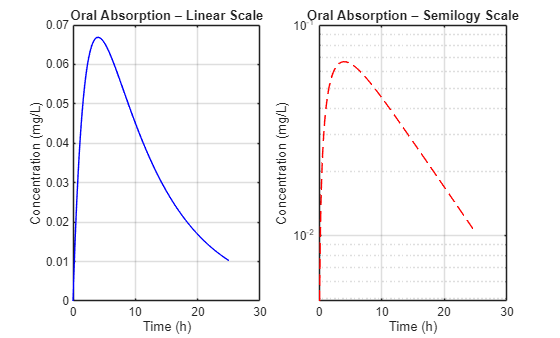

clear

% Parameters
D = 10;       % mg
CL = 10;      % L/h
V = 100;      % L
ka = 0.5;     % /h
t = 0:0.1:25; % time vector (h)

% Concentration (oral absorption)
Cp = (D * ka / (V * ka - CL)) * (exp(-CL/V * t) - exp(-ka * t));

% Linear scale plot
figure()
subplot(1,2,1),plot(t, Cp, 'b-');
xlabel('Time (h)');
ylabel('Concentration (mg/L)');
title('Oral Absorption – Linear Scale');
grid on;
% Semilogy scale plot
subplot(1,2,2),semilogy(t, Cp, '--r');
xlabel('Time (h)');
ylabel('Concentration (mg/L)');
title('Oral Absorption – Semilogy Scale');
grid on;